# Capítulo 1. Introducción a señales y sistemas

### Resultado de aprendizaje

Al finalizar este capítulo, el estudiante será capaz de identificar los conceptos fundamentales de señal y sistema, reconocer su importancia en ingeniería y representar señales básicas mediante MATLAB Live Script.

###  1.1 Introducción

El estudio de señales y sistemas constituye una base esencial para la formación en ingeniería, especialmente en áreas como telecomunicaciones, electrónica, control automático, procesamiento digital de señales, instrumentación, automatización e inteligencia artificial aplicada.

Una señal puede entenderse como una función que contiene información sobre el comportamiento de un fenómeno físico, eléctrico, mecánico, biológico o digital.

Un sistema es un conjunto de elementos o procesos que recibe una señal de entrada, la transforma de alguna manera y genera una señal de salida.

### 1.2 Concepto de señal

Una señal es una función matemática que representa la variación de una magnitud respecto a una o más variables independientes.

Señal continua:


$$x(t)$$


Señal discreta:


$$x[n]$$


### 1.3 Ejemplo de señal continua

Una señal sinusoidal puede representarse como:


$$x(t)=A\sin(2\pi f t)$$


## Ejemplo 1: Señal sinusoidal continua

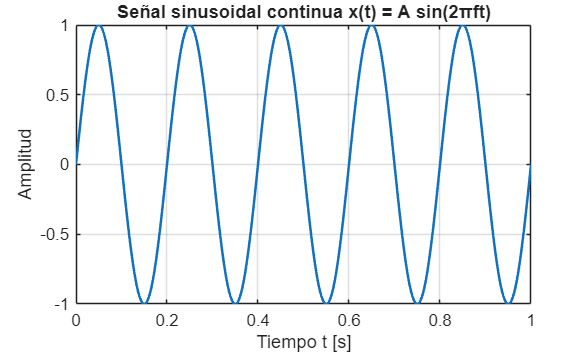

clc;
clear;
close all;

% Parámetros de la señal
A = 1;          % Amplitud
f = 5;          % Frecuencia en Hz
t = 0:0.001:1;  % Vector de tiempo continuo aproximado

% Definición de la señal
x = A*sin(2*pi*f*t);

% Gráfica
figure;
plot(t, x, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo t [s]');
ylabel('Amplitud');
title('Señal sinusoidal continua x(t) = A sin(2πft)');

## Interpretación del resultado

La gráfica obtenida representa una señal sinusoidal continua aproximada mediante MATLAB. Aunque MATLAB trabaja con valores discretos en memoria, al utilizar un paso de tiempo muy pequeño, la representación visual se aproxima al comportamiento de una señal continua.

En este ejemplo, la señal tiene una amplitud de 1 y una frecuencia de 5 Hz.

## 1.5 Concepto de sistema

Un sistema es un modelo que transforma una señal de entrada en una señal de salida:


$$y(t)=T\{x(t)\}$$


Si un sistema amplifica una señal de entrada por un factor de 2:


$$y(t)=2x(t)$$


## Ejemplo 2: Sistema amplificador

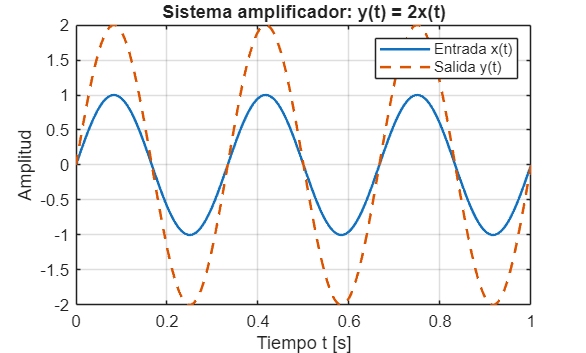

clc;
clear;
close all;

% Señal de entrada
A = 1;
f = 3;
t = 0:0.001:1;
x = A*sin(2*pi*f*t);

% Sistema amplificador
ganancia = 2;
y = ganancia*x;

% Gráfica de entrada y salida
figure;
plot(t, x, 'LineWidth', 1.5);
hold on;
plot(t, y, '--', 'LineWidth', 1.5);
grid on;

xlabel('Tiempo t [s]');
ylabel('Amplitud');
title('Sistema amplificador: y(t) = 2x(t)');
legend('Entrada x(t)', 'Salida y(t)');

## Interpretación del sistema amplificador

El sistema toma la señal de entrada x(t) y genera una salida y(t) con el doble de amplitud. La frecuencia de la señal no cambia, pero su amplitud aumenta. Este tipo de sistema se relaciona con amplificadores electrónicos.

### 1.8 Señal discreta básica

Una señal discreta se define únicamente para valores enteros del índice n:


$$x[n]=\sin(2\pi f nT_s)$$


## Ejemplo 3: Señal sinusoidal discreta

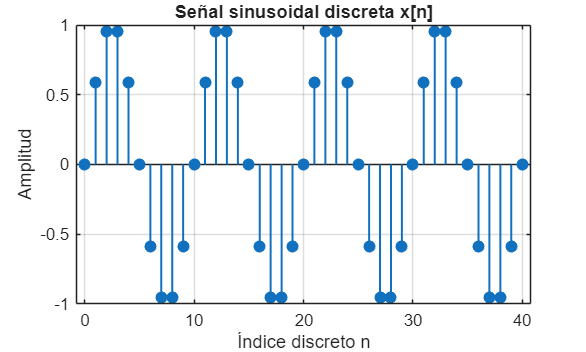

clc;
clear;
close all;

% Parámetros
A = 1;
f = 2;           % Frecuencia en Hz
Fs = 20;         % Frecuencia de muestreo en Hz
Ts = 1/Fs;       % Periodo de muestreo
n = 0:40;        % Índice discreto

% Señal discreta
x = A*sin(2*pi*f*n*Ts);

% Gráfica
figure;
stem(n, x, 'filled', 'LineWidth', 1.2);
grid on;

xlabel('Índice discreto n');
ylabel('Amplitud');
title('Señal sinusoidal discreta x[n]');

## Comparación entre señal continua y señal discreta

En ingeniería, muchas señales físicas son continuas por naturaleza, como el sonido, la temperatura, la presión o el voltaje. Para procesarlas en una computadora, microcontrolador o sistema embebido, deben representarse mediante muestras discretas.

## Ejemplo 4: Comparación entre señal continua y discreta

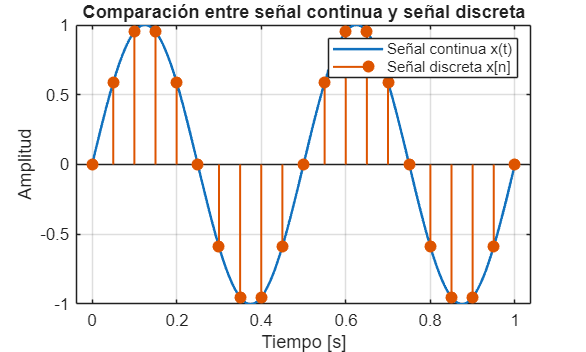

clc;
clear;
close all;

% Señal continua aproximada
A = 1;
f = 2;
t = 0:0.001:1;
x_continua = A*sin(2*pi*f*t);

% Señal discreta
Fs = 20;
Ts = 1/Fs;
n = 0:Fs;
t_discreto = n*Ts;
x_discreta = A*sin(2*pi*f*t_discreto);

% Gráfica comparativa
figure;
plot(t, x_continua, 'LineWidth', 1.5);
hold on;
stem(t_discreto, x_discreta, 'filled', 'LineWidth', 1.2);
grid on;

xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Comparación entre señal continua y señal discreta');
legend('Señal continua x(t)', 'Señal discreta x[n]');

## Aplicación en ingeniería

En telecomunicaciones, una señal puede representar información transmitida mediante ondas electromagnéticas. En electrónica, puede representar voltajes y corrientes. En control automático, puede representar velocidad, posición o temperatura. En inteligencia artificial aplicada, las señales pueden provenir de sensores y ser utilizadas para reconocimiento de patrones, predicción o toma de decisiones.

## Ejemplo 5: Señal simulada de temperatura

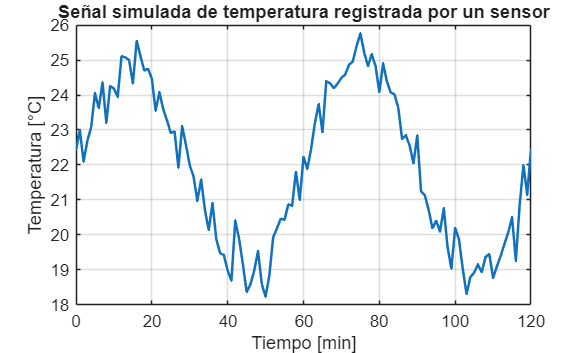

clc;
clear;
close all;

% Tiempo de medición
t = 0:1:120;  % minutos

% Temperatura simulada
temperatura = 22 + 3*sin(2*pi*t/60) + 0.5*randn(size(t));

% Gráfica
figure;
plot(t, temperatura, 'LineWidth', 1.5);
grid on;

xlabel('Tiempo [min]');
ylabel('Temperatura [°C]');
title('Señal simulada de temperatura registrada por un sensor');

## Actividades propuestas

1. Modifique la frecuencia de la señal sinusoidal continua del Ejemplo 1. 2. Cambie la ganancia del sistema amplificador a 0.5, 3 y -1. 3. Aumente y disminuya la frecuencia de muestreo del Ejemplo 3. 4. Genere una señal discreta de voltaje de un sensor durante 60 segundos. 5. Explique la diferencia entre señal continua, señal discreta y sistema.

### Conclusiones

Las señales permiten representar matemáticamente información generada por fenómenos físicos, eléctricos, mecánicos o digitales. Los sistemas permiten transformar dichas señales para analizarlas, modificarlas o extraer información útil.

MATLAB Live Script facilita el aprendizaje de señales y sistemas porque permite combinar teoría, ecuaciones, código ejecutable, gráficos e interpretación en un solo entorno.

### Bibliografía básica

- Oppenheim, A. V., Willsky, A. S., & Nawab, S. H. Señales y sistemas.

- Lathi, B. P. Linear Systems and Signals.

- Haykin, S., & Van Veen, B. Signals and Systems.

- MathWorks Documentation. MATLAB Live Editor.